#  HW 3 - METHODS FOR EIGENVALUES - TESTING METHODS

## Setting parameters

clear all
maxIter = 10000;
relTol = 1e-10;
tol_eigval = 1e-7;
tol_eigvec = 1e-4;

## 1. POWER AND INVERSE POWER METHOD

## Computing 1st and last eigenpairs

we use :

- power method --> A must have | `lambda_1 `| > |  `lambda_i | for all i>1`

- inverse power method  --> A must have   | `lambda_n `| < |  `lambda_i | for all i<n`

### Matrix definition for Power and Inverse power method

% set seed for reproducibility
seed = 44;
rng(seed);
n=9;
lambda = zeros(n,1);
% generating a random vector of different eigenvalues 
arequal = 1;
while arequal == 1
    lambda = rand(n,1);
    lambda = sort(lambda, 'descend');
    % for small n, we create a matrix with n distinct eigenvalues
    if n<10
        for i=1:n-1
            arequal = abs(lambda(i)) == abs(lambda(i+1)) ;
        end
    % for large n we only check that the fisrt and last two are
    % different
    else
        arequal = (abs(lambda(1)) == abs(lambda(2))) | (abs(lambda(n)) == abs(lambda(n-1)));
    end
end

% creating a diagonal matrix of eigenvalues
D = diag(lambda);
% generating a random matrix
P = randn(length(lambda)); 
% creating the random matrix A similar to D
A = P \ D * P; % A = P^-1 D P (A solves AP = DP)
% creating a symmetric positive definite matrix similar to D
[Q, ~] = qr(randn(n));
As = Q' * D * Q;

### Power method

eigenvalue is correct


residual Av - lambdav : 8.293623e-11

also eigenvector is correct


execution time : 7.565700e-03

number of iterations : 145

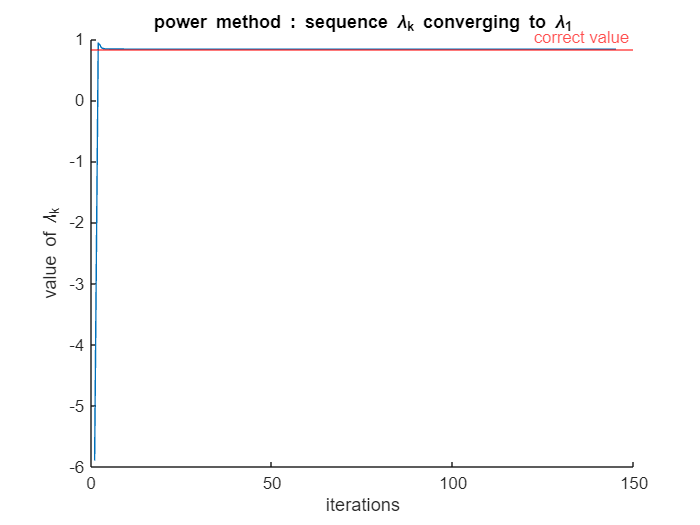

% power method
v0 = ones(n, 1);
tic;
[lambda_1, v1, lambda_seq_pm] = power_method(A, v0, maxIter, relTol);
ex_time_pm = toc;
% check if eigenvalue is correct
if abs(lambda_1 - lambda(1)) < tol_eigval
    disp('eigenvalue is correct');
    % check if eigenvector is correct too
    residual = abs(A*v1 - lambda_1*v1 );
    fprintf('residual Av - lambdav : %d', norm(residual, 2));
    if all(residual < tol_eigval)
        disp('also eigenvector is correct');
    end

    % print execution time
    fprintf('execution time : %d', ex_time_pm);

    % print number of iterations for convergence
    kpm = length(lambda_seq_pm);
    fprintf('number of iterations : %d', kpm);

    % plot of the sequence
    figure;
    hold on;
    plot(1:kpm, lambda_seq_pm);
    xlabel('iterations');
    ylabel('value of \lambda_k');
    title('power method : sequence \lambda_k converging to \lambda_1');
    yline(lambda(1), 'r', 'correct value');
    hold off;
end

% experimental order of converge of the method
ekm2 = norm( lambda_seq_pm(kpm-2) - lambda_seq_pm(kpm-3), 2);
ekm1 = norm( lambda_seq_pm(kpm-1) - lambda_seq_pm(kpm-2), 2);
ek = norm( lambda_seq_pm(kpm) - lambda_seq_pm(kpm-1), 2);

ppm = log(ek/ekm1) / log(ekm1/ekm2);
fprintf('experimental order of convergence : %d', ppm);

experimental order of convergence : 9.971075e-01

as expected, the order of convergence is linear.

### Inverse power method

eigenvalue is correct


residual Av - lambdav : 1.621325e-12

also eigenvector is correct


execution time : 1.151960e-02

number of iterations : 19

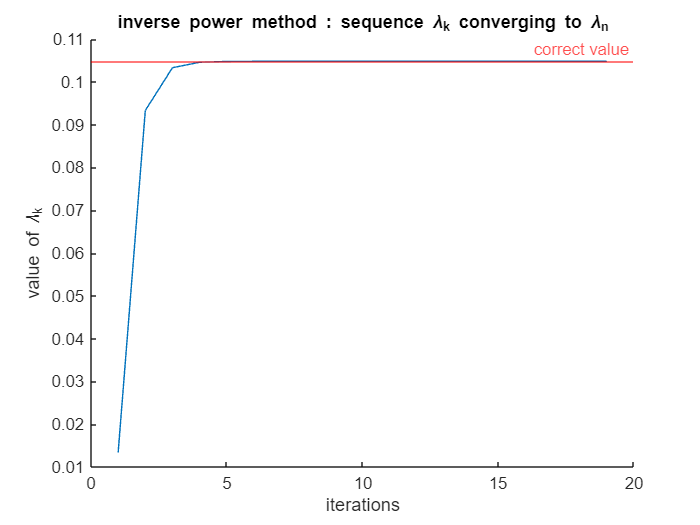

% inverse power method
v0 = ones(n, 1); %user set
tic;
[lambda_n, vn, lambda_seq_ipm] = inverse_power_method(A, v0, maxIter, relTol);
ex_time_ipm = toc;
% check if eigenvalue is correct
if abs(lambda_n - lambda(n)) < tol_eigval
    disp('eigenvalue is correct');
    % check if eigenvector is correct too
    residual = abs(A*vn - lambda_n*vn );
    fprintf('residual Av - lambdav : %d', norm(residual, 2));
    if all(residual < tol_eigvec)
        disp('also eigenvector is correct');
    end

    % print execution time
    fprintf('execution time : %d', ex_time_ipm);

    % print number of iterations for convergence
    kipm = length(lambda_seq_ipm);
    fprintf('number of iterations : %d', kipm);

    % plot of the sequence
    figure;
    hold on;
    % NB: plot of the inverse of the sequence (sequence is muk not lambdak)
    plot(1:kipm, 1./lambda_seq_ipm); 
    xlabel('iterations');
    ylabel('value of \lambda_k');
    title('inverse power method : sequence \lambda_k converging to \lambda_n');
    yline(lambda(n), 'r', 'correct value');
    hold off;
end

% experimental order of converge of the method
ekm2 = norm( lambda_seq_ipm(kipm-2) - lambda_seq_ipm(kipm-3), 2);
ekm1 = norm( lambda_seq_ipm(kipm-1) - lambda_seq_ipm(kipm-2), 2);
ek = norm( lambda_seq_ipm(kipm) - lambda_seq_ipm(kipm-1), 2);
pipm = log(ek/ekm1) / log(ekm1/ekm2);
fprintf('experimental order of convergence : %d', pipm);

experimental order of convergence : 1.006076e+00

as expected, the order of convergence is linear.

## Computing successive eigenvalues

we use: 

- shifting method  --> A must be symmetric and | lambda_2 | > | lambda_i | for all i>2 (for PM)

- deflation methods --> A must have  | lambda_2 | > | lambda_i | for all i>2

### Shifting + power method

eigenvalue 2 is correct


residual Av - lambdav : 6.188377e-06

also eigenvector is correct


execution time : 7.885100e-03

number of iterations : 49

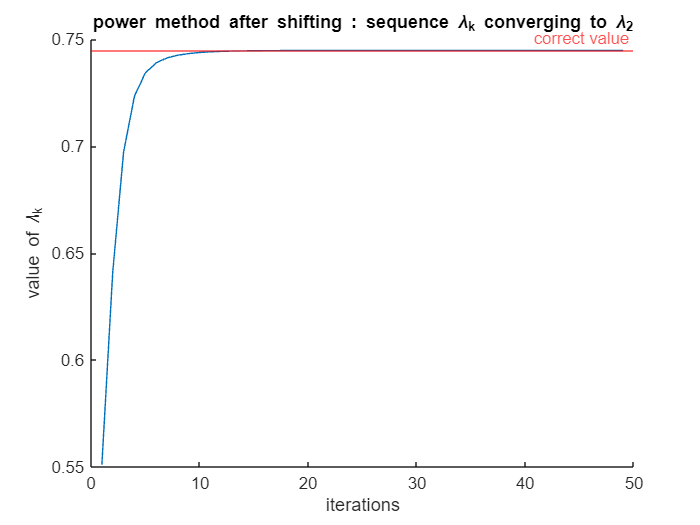

experimental order of convergence : 1.000011e+00

% computing the 2nd greatest eigenvalue of A using shifting and power
% method 
tic;
[lambda_1s, v1s, ~] = power_method(As, v0, maxIter, relTol);
Ashift = shifting_method(As,lambda_1s, v1s);
[lambda_2s, v2s, lambda_seq_pm2] = power_method(Ashift, v0, maxIter, relTol);
ex_time_shift = toc;

% check if eigenvalue is correct
if abs(lambda_2s - lambda(2)) < tol_eigval
    disp('eigenvalue 2 is correct');
    % check if eigenvector is correct too
    residual= abs(As*v2s - lambda_2s*v2s );
    fprintf('residual Av - lambdav : %d', norm(residual, 2));
    if all(residual < tol_eigvec)
        disp('also eigenvector is correct');
    end

    % print execution time
    fprintf('execution time : %d', ex_time_shift);

    % print number of iterations for convergence
    kshift = length(lambda_seq_pm2);
    fprintf('number of iterations : %d', kshift);

    % plot of the sequence
    figure;
    hold on;
    plot(1:kshift, lambda_seq_pm2);
    xlabel('iterations');
    ylabel('value of \lambda_k');
    title('power method after shifting : sequence \lambda_k converging to \lambda_2');
    yline(lambda(2), 'r', 'correct value');
    hold off;

    % experimental order of converge of the method
    ekm2 = norm( lambda_seq_pm2(kshift-2) - lambda_seq_pm2(kshift-3), 2);
    ekm1 = norm( lambda_seq_pm2(kshift-1) - lambda_seq_pm2(kshift-2), 2);
    ek = norm( lambda_seq_pm2(kshift) - lambda_seq_pm2(kshift-1), 2);
    pshift = log(ek/ekm1) / log(ekm1/ekm2);
    fprintf('experimental order of convergence : %d', pshift);
end

### Deflation + power method

eigenvalue 2 is correct


residual Av - lambdav : 1.781375e+00

execution time : 1.543540e-02

number of iterations : 109

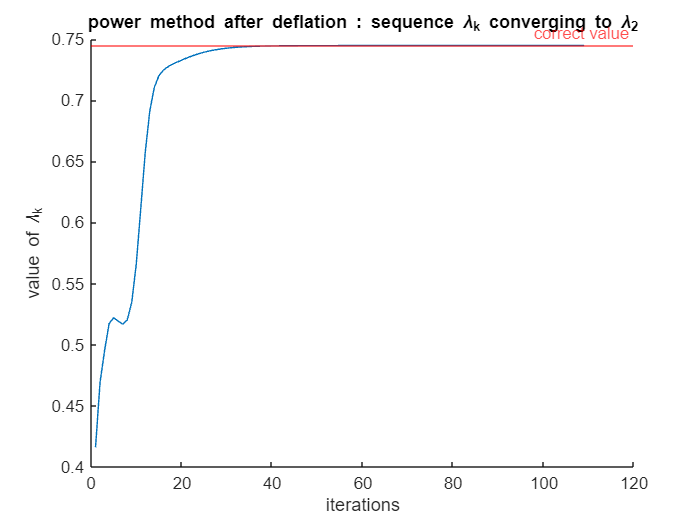

experimental order of convergence : 9.999588e-01

% deflation method to compute 2nd eigenvalue of A
tic;
[P_bar, small_A, b, PAP] = deflation_method(A, v1);
[lambda_2, v2nm1, lambda_seq_def] = power_method(small_A, v0(1:n-1), maxIter, relTol);
alpha = -b'*v2nm1 / (lambda_1 - lambda_2);
v2bar = [alpha; v2nm1];
v2 = P_bar*v2bar;
ex_time_def = toc;

% check if eigenvalue is correct
if abs(lambda_2 - lambda(2)) < tol_eigval
    disp('eigenvalue 2 is correct');
    % check if eigenvector is correct too
    residual = abs(A*v2 - lambda_2*v2 );
    fprintf('residual Av - lambdav : %d', norm(residual, 2));
    if all(residual < tol_eigvec)
        disp('also eigenvector is correct');
    end

    % print execution time
    fprintf('execution time : %d', ex_time_def);

    % print number of iterations for convergence
    kdef = length(lambda_seq_def);
    fprintf('number of iterations : %d', kdef);

    % plot of the sequence
    figure;
    hold on;
    plot(1:kdef, lambda_seq_def);
    xlabel('iterations');
    ylabel('value of \lambda_k');
    title('power method after deflation : sequence \lambda_k converging to \lambda_2');
    yline(lambda(2), 'r', 'correct value');
    hold off;

    % experimental order of converge of the method
    ekm2 = norm( lambda_seq_def(kdef-2) - lambda_seq_def(kdef-3), 2);
    ekm1 = norm( lambda_seq_def(kdef-1) - lambda_seq_def(kdef-2), 2);
    ek = norm( lambda_seq_def(kdef) - lambda_seq_def(kdef-1), 2);
    pdef = log(ek/ekm1) / log(ekm1/ekm2);
    fprintf('experimental order of convergence : %d', pdef);
end

### Deflation + inverse power method

eigenvalue 2 is correct


residual Av - lambdav : 1.149827e+00

execution time : 2.672740e-02

number of iterations : 2902

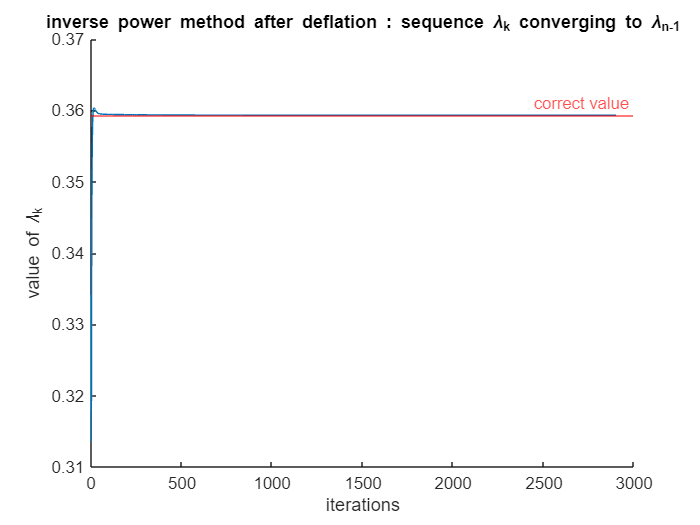

experimental order of convergence : 9.994474e-01

% deflation method to compute 2nd eigenvalue of A
tic;
[eigenvalues_definv, eigenvectors_definv, mu_seq] = compute_m_smallest_eigenvalues(A,2,'yes', maxIter, relTol);
ex_time_definv = toc;
lambda_nm1 = eigenvalues_definv(2);
vnm1 = eigenvectors_definv(:, 2);
% check if eigenvalue is correct
if abs(lambda_nm1 - lambda(n-1)) < tol_eigval
    disp('eigenvalue 2 is correct');
    % check if eigenvector is correct too
    residual = abs(A*vnm1 - lambda_nm1*vnm1 );
    fprintf('residual Av - lambdav : %d', norm(residual, 2));
    if all(residual < tol_eigvec)
        disp('also eigenvector is correct');
    end

    % print execution time
    fprintf('execution time : %d', ex_time_definv);

    % print number of iterations for convergence
    kipmdef = length(mu_seq);
    fprintf('number of iterations : %d', kipmdef);

    % plot of the sequence
    figure;
    hold on;
    % NB: plot of the inverse of the sequence (sequence is muk not lambdak)
    plot(1:kipmdef, 1./mu_seq); 
    xlabel('iterations');
    ylabel('value of \lambda_k');
    title('inverse power method after deflation : sequence \lambda_k converging to \lambda_{n-1}');
    yline(lambda(n-1), 'r', 'correct value');
    hold off;

    % experimental order of converge of the method
    ekm2 = norm(mu_seq(kipmdef-2) - mu_seq(kipmdef-3), 2);
    ekm1 = norm(mu_seq(kipmdef-1) - mu_seq(kipmdef-2), 2);
    ek = norm(mu_seq(kipmdef) - mu_seq(kipmdef-1), 2);
    pdefinv = log(ek/ekm1) / log(ekm1/ekm2);
    fprintf('experimental order of convergence : %d', pdefinv);
end

## Computing all eigenvalues (only for small matrices)

### Deflation + inverse power method

% only for small matrices
if n<10
    % Deflation method + inverse power method
    tic;
    [eigenvalues_A, ~, ~] = compute_m_smallest_eigenvalues(A,n,'no', maxIter, relTol);
    ex_time_ms = toc;
    
    % print execution time
    fprintf('execution time : %d', ex_time_ms);
    for i=1:n
        lambdac =sort(lambda);
        % check if eigenvalues are correct
        if abs(eigenvalues_A(i) - lambdac(i)) < tol_eigval
            fprintf('eigenvalue %d is correct \n', i);
        end
    end
end

execution time : 3.322860e-02

eigenvalue 1 is correct 
eigenvalue 2 is correct 
eigenvalue 3 is correct 
eigenvalue 4 is correct 
eigenvalue 5 is correct 
eigenvalue 6 is correct 
eigenvalue 7 is correct 
eigenvalue 8 is correct 
eigenvalue 9 is correct 


### Deflation + power method

% only for small matrices
if n<10
    % Deflation method + power method
    tic;
    [eigenvalues_Ag, ~] = compute_m_greatest_eigenvalues(A,n,'no', maxIter, relTol);
    ex_time_mg = toc;
    
    % print execution time
    fprintf('execution time : %d', ex_time_mg);
    for i=1:n
        % check if eigenvalues are correct
        if abs(eigenvalues_Ag(i) - lambda(i)) < tol_eigval
            fprintf('eigenvalue %d is correct \n', i);
        end
    end
end

execution time : 1.428600e-02

eigenvalue 1 is correct 
eigenvalue 2 is correct 
eigenvalue 3 is correct 
eigenvalue 4 is correct 
eigenvalue 5 is correct 
eigenvalue 6 is correct 
eigenvalue 9 is correct 


## Computing eigenvalues and approximating eigenvectors (only for small matrices)

tests for:

- A random 

- Auh upper hessenberg

- Atd tridiagonal

- Ad diagonal

% D diagonal matrix of eigenvalues 
% Ad = D;
% As = d;
% creating a upper hessemberg matrix similar to A
% Auh = similar_hessemberg(A);
% % creating a tridiagonal matrix similar to A
% applying lanczos method to the SPD similar to A As get a tridiagonal matrix similar to A
% [Atd, ~, ~, ~, ~, ~]= lanczos_method(As, 'eig', ones(n,1), tol_eigval);

### Shifting + power method

% shifting and power method (contained in the function compute_eigenpairs)
tic;
[eigenvalues_PmS, eigenvectors_PmS] = compute_eigenpairs(As, maxIter, relTol);
ex_time_PmS = toc;
% print execution time
fprintf('execution time : %d', ex_time_PmS);

execution time : 1.054420e-02

for i=1:n
    % check if eigenvalues are correct
    if abs(eigenvalues_PmS(i) - lambda(i)) < tol_eigval
        fprintf('eigenvalue %d is correct', i);
        % check if eigenvector is correct too
        residual = norm(As*eigenvectors_PmS(:, i) - eigenvalues_PmS(i)*eigenvectors_PmS(:, i), 2);
        if residual < tol_eigvec
            disp('also eigenvector is correct');
        else
            fprintf('residual for eigenvector %d is : %d', i, residual);
        end
    end
end

eigenvalue 1 is correct

also eigenvector is correct


eigenvalue 2 is correct

also eigenvector is correct


eigenvalue 3 is correct

also eigenvector is correct


eigenvalue 4 is correct

also eigenvector is correct


eigenvalue 5 is correct

also eigenvector is correct


eigenvalue 6 is correct

also eigenvector is correct


eigenvalue 7 is correct

also eigenvector is correct


eigenvalue 8 is correct

also eigenvector is correct


eigenvalue 9 is correct

also eigenvector is correct


### Deflation method + inverse power method

Computing all eigenalues and eigenvectors in increasing order

% Deflation method + inverse power method 
tic;
[eigenvalues_A, eigenvectors_A, j] = compute_m_smallest_eigenvalues(A,n,'yes', maxIter, relTol);
ex_time_ms = toc;

% print execution time
fprintf('execution time : %d', ex_time_ms);

execution time : 2.397320e-02

for i=1:n
    lambdac =sort(lambda);
    % check if eigenvalues are correct
    if abs(eigenvalues_A(i) - lambdac(i)) < tol_eigval
        fprintf('eigenvalue %d is correct \n', i);
        % check if eigenvector is correct too
        residual = norm(A*eigenvectors_A(:, i) - eigenvalues_A(i)*eigenvectors_A(:, i), 2);
        if residual < tol_eigvec
            disp('also eigenvector is correct');
        else
            fprintf('residual for eigenvector %d is : %d', i, residual);
        end
    end
end

eigenvalue 1 is correct 


also eigenvector is correct


eigenvalue 2 is correct 


residual for eigenvector 2 is : 1.149827e+00

eigenvalue 3 is correct 


residual for eigenvector 3 is : 1.156587e+00

eigenvalue 4 is correct 


residual for eigenvector 4 is : 1.364079e+00

eigenvalue 5 is correct 


residual for eigenvector 5 is : 1.470349e+00

eigenvalue 6 is correct 


residual for eigenvector 6 is : 2.143756e+00

eigenvalue 7 is correct 


residual for eigenvector 7 is : 2.202685e+00

eigenvalue 8 is correct 


residual for eigenvector 8 is : 1.861634e+00

eigenvalue 9 is correct 


residual for eigenvector 9 is : 2.872173e+00

### Deflation + power method

Computing all eigenalues and eigenvectors in decreasing order

% Deflation method + power method
tic;
[eigenvalues_Ag, eigenvectors_Ag] = compute_m_greatest_eigenvalues(A,n,'yes', maxIter, relTol);
ex_time_mg = toc;

% print execution time
fprintf('execution time : %d', ex_time_mg);

execution time : 1.597470e-02

for i=1:n
    % check if eigenvalues are correct
    if abs(eigenvalues_Ag(i) - lambda(i)) < tol_eigval*10
        fprintf('eigenvalue %d is correct \n', i);
        % check if eigenvector is correct too
        residual = norm(A*eigenvectors_Ag(:, i) - eigenvalues_Ag(i)*eigenvectors_Ag(:, i), 2);
        if residual < tol_eigvec
            disp('also eigenvector is correct');
        else
            fprintf('residual for eigenvector %d is : %d', i, residual);
        end
    end
end

eigenvalue 1 is correct 


also eigenvector is correct


eigenvalue 2 is correct 


residual for eigenvector 2 is : 3.142219e-01

eigenvalue 3 is correct 


residual for eigenvector 3 is : 5.304022e+00

eigenvalue 4 is correct 


residual for eigenvector 4 is : 4.739060e+00

eigenvalue 5 is correct 


residual for eigenvector 5 is : 1.078927e+01

eigenvalue 6 is correct 


residual for eigenvector 6 is : 9.498743e+00

eigenvalue 7 is correct 


residual for eigenvector 7 is : 2.519037e+00

eigenvalue 8 is correct 


residual for eigenvector 8 is : 3.036901e+00

eigenvalue 9 is correct 


residual for eigenvector 9 is : 1.301403e+01

## 2. QR METHOD 

## Computing all eigenvalues

### Matrix definition for QR method test

% set seed for reproducibility
seed = 32;
rng(seed);
n=9;
% generating a random matrix
A=rand(n,n);
lambda=sort(eig(A), 'descend');
% % A symmetric potive definite
% A = A'*A + eye(n,n)*n;
% lambda=sort(eig(A), 'descend');

### Qr method (basic implementation)

% QR method (basic implementation)
tic;
% computing eigenvalues only
[eigenvalues_QR, ~, Ak, kQR] = QR_method(A, 'no', relTol, maxIter, 'basic');
eigenvalues_QR = sort(eigenvalues_QR, 'descend');
ex_time_QR = toc;
disp('the triangular matrix returned by QR method is:');

the triangular matrix returned by QR method is:


disp(Ak);

    4.4388    0.0541    0.2256   -0.4077    0.1586    0.6690   -0.2947    0.3261   -0.0058
         0   -0.0183   -0.5547    0.1172    0.0417   -0.4821    0.0105   -0.4888   -0.1791
         0    0.9347   -0.2323   -0.1962    0.1436    0.2955   -0.0537   -0.1840    0.5428
         0    0.0000   -0.0000   -0.5053    0.5560   -0.0772    0.0291    0.0798   -0.2506
         0   -0.0000    0.0000   -0.2474   -0.5723   -0.3565    0.0502   -0.1086   -0.1913
         0         0         0   -0.0000   -0.0000    0.5983   -0.3171   -0.1917   -0.1447
         0         0    0.0000         0   -0.0000    0.3915    0.1184    0.0208   -0.0782
         0         0    0.0000         0         0         0         0   -0.3279    0.4441
         0         0    0.0000         0         0    0.0000   -0.0000         0    0.2839



% print execution time
fprintf('execution time : %d', ex_time_QR);

execution time : 1.977026e-01

% print number of iterations for convergence
fprintf('number of iterations : %d', kQR);

number of iterations : 9999

for i=1:n
    % check if eigenvalues are correct
    if abs(eigenvalues_QR(i) - lambda(i)) < tol_eigval
        fprintf('eigenvalue %d is correct \n', i);
    end
end

eigenvalue 1 is correct 
eigenvalue 2 is correct 
eigenvalue 3 is correct 
eigenvalue 4 is correct 
eigenvalue 5 is correct 
eigenvalue 6 is correct 
eigenvalue 7 is correct 
eigenvalue 8 is correct 
eigenvalue 9 is correct 


### QR method with upper Hessenberg implementation

% QR method (upper_hessemberg implementation) for a matrix with different eigenvalues
tic;
[eigenvalues_QR_uh, ~, Ak_uh, kQRuh] = QR_method(A,'no', relTol, maxIter, 'up_hess');
eigenvalues_QR_uh= sort(eigenvalues_QR_uh , 'descend');
ex_time_QR_uh = toc;
disp('the triangular matrix returned by QR method is:');

the triangular matrix returned by QR method is:


disp(Ak_uh);

    4.4388    0.2259    0.0528    0.0626   -0.4330    0.2318    0.6933    0.3261    0.0058
         0   -0.2301    0.9360   -0.0290   -0.2409    0.1571    0.2527   -0.1869   -0.5418
         0   -0.5535   -0.0205   -0.0938    0.0829   -0.3173   -0.3654   -0.4877    0.1822
         0   -0.0000   -0.0000   -0.4238    0.2935    0.1913    0.2968    0.0553   -0.2899
         0    0.0000   -0.0000   -0.5099   -0.6537    0.0733    0.0797    0.1229    0.1240
         0         0    0.0000    0.0000         0    0.3724    0.5966   -0.1135    0.1552
         0         0         0    0.0000         0   -0.1119    0.3443   -0.1558    0.0545
         0         0         0         0         0         0   -0.0000   -0.3279   -0.4441
         0         0         0    0.0000         0         0    0.0000    0.0000    0.2839



% print execution time
fprintf('execution time : %d', ex_time_QR_uh);

execution time : 1.769203e-01

% print number of iterations for convergence
fprintf('number of iterations : %d', kQRuh);

number of iterations : 9999

for i=1:n
    % check if eigenvalues are correct
    if abs(eigenvalues_QR_uh(i) - lambda(i)) < tol_eigval
        fprintf('eigenvalue %d is correct \n', i);
    end
end

eigenvalue 1 is correct 
eigenvalue 2 is correct 
eigenvalue 3 is correct 
eigenvalue 4 is correct 
eigenvalue 5 is correct 
eigenvalue 6 is correct 
eigenvalue 7 is correct 
eigenvalue 8 is correct 
eigenvalue 9 is correct 


### QR method with shifting and upper Hessemberg implementation

% QR method with shifting (upper_hessemberg implementation)
tic;
[eigenvalues_QR_shift, kQRshift_seq] = QR_shift_method(A, maxIter, relTol);
eigenvalues_QR_shift = sort(eigenvalues_QR_shift, 'descend');
ex_time_QR_shift = toc;
% print execution time
fprintf('execution time : %d', ex_time_QR_shift);

execution time : 6.467160e-02

% print number of iterations for convergence
for i=1:n-1
    fprintf('number of iterations for %d iteration : %d \n',i, kQRshift_seq(i));
end

number of iterations for 1 iteration : 5 
number of iterations for 2 iteration : 10000 
number of iterations for 3 iteration : 10000 
number of iterations for 4 iteration : 10000 
number of iterations for 5 iteration : 10000 
number of iterations for 6 iteration : 10000 
number of iterations for 7 iteration : 10000 
number of iterations for 8 iteration : 10000 


for i=1:n
    % check if eigenvalues are correct
    if abs(eigenvalues_QR_shift(i) - lambda(i)) < tol_eigval
        fprintf('eigenvalue %d is correct \n', i);
    end
end

eigenvalue 1 is correct 
eigenvalue 2 is correct 
eigenvalue 3 is correct 
eigenvalue 4 is correct 
eigenvalue 5 is correct 
eigenvalue 6 is correct 
eigenvalue 7 is correct 
eigenvalue 8 is correct 


## Computing eigenvalues and approximating eigenvectors

### Qr method basic implementation

% QR method (basic implementation) for a matrix with different eigenvalues
tic;
[eigenvalues_QR, eigenvectors_QR, Ak, kQR] = QR_method(A, 'yes', relTol, maxIter, 'basic');
ex_time_QR = toc;
disp('the triangular matrix returned by QR method is:');

the triangular matrix returned by QR method is:


disp(Ak);

    4.4388    0.0541    0.2256   -0.4077    0.1586    0.6690   -0.2947    0.3261   -0.0058
         0   -0.0183   -0.5547    0.1172    0.0417   -0.4821    0.0105   -0.4888   -0.1791
         0    0.9347   -0.2323   -0.1962    0.1436    0.2955   -0.0537   -0.1840    0.5428
         0    0.0000   -0.0000   -0.5053    0.5560   -0.0772    0.0291    0.0798   -0.2506
         0   -0.0000    0.0000   -0.2474   -0.5723   -0.3565    0.0502   -0.1086   -0.1913
         0         0         0   -0.0000   -0.0000    0.5983   -0.3171   -0.1917   -0.1447
         0         0    0.0000         0   -0.0000    0.3915    0.1184    0.0208   -0.0782
         0         0    0.0000         0         0         0         0   -0.3279    0.4441
         0         0    0.0000         0         0    0.0000   -0.0000         0    0.2839



% print number of iterations for convergence
fprintf('number of iterations for convergence : %d', kQR);

number of iterations for convergence : 9999

% print execution time
fprintf('execution time : %d', ex_time_QR);

execution time : 1.727526e-01

for i=1:n
    % check if eigenvalues are correct
    sorted = sort(eigenvalues_QR, 'descend');
    if abs( sorted(i) - lambda(i)) < tol_eigval
        fprintf('eigenvalue %d is correct \n', i);
        % check if eigenvector is correct too
        residual = norm(A*eigenvectors_QR(:, i) - eigenvalues_QR(i)*eigenvectors_QR(:, i), 2);
        if residual < tol_eigvec
            disp('also eigenvector is correct');
        else
            fprintf('residual for eigenvector %d is : %d', i, residual);
        end
    end
end

eigenvalue 1 is correct 


also eigenvector is correct


eigenvalue 2 is correct 


residual for eigenvector 2 is : 1.055657e+00

eigenvalue 3 is correct 


residual for eigenvector 3 is : 8.960950e-01

eigenvalue 4 is correct 


residual for eigenvector 4 is : 6.916616e-01

eigenvalue 5 is correct 


residual for eigenvector 5 is : 8.983490e-01

eigenvalue 6 is correct 


residual for eigenvector 6 is : 1.082390e+00

eigenvalue 7 is correct 


residual for eigenvector 7 is : 9.814773e-01

eigenvalue 8 is correct 


residual for eigenvector 8 is : 8.070444e-01

eigenvalue 9 is correct 


residual for eigenvector 9 is : 9.692089e-01

### QR method with upper hessemberg matrix 

% QR method (upper_hessemberg implementation) for a matrix with different eigenvalues
tic;
[eigenvalues_QR_uh, eigenvectors_QR_uh, Ak_uh, kQR_uh] = QR_method(A,'yes', relTol, maxIter, 'up_hess');
ex_time_QR_uh = toc;
disp('the triangular matrix returned by QR method is:');

the triangular matrix returned by QR method is:


disp(Ak_uh);

    4.4388    0.2259    0.0528    0.0626   -0.4330    0.2318    0.6933    0.3261    0.0058
         0   -0.2301    0.9360   -0.0290   -0.2409    0.1571    0.2527   -0.1869   -0.5418
         0   -0.5535   -0.0205   -0.0938    0.0829   -0.3173   -0.3654   -0.4877    0.1822
         0   -0.0000   -0.0000   -0.4238    0.2935    0.1913    0.2968    0.0553   -0.2899
         0    0.0000   -0.0000   -0.5099   -0.6537    0.0733    0.0797    0.1229    0.1240
         0         0    0.0000    0.0000         0    0.3724    0.5966   -0.1135    0.1552
         0         0         0    0.0000         0   -0.1119    0.3443   -0.1558    0.0545
         0         0         0         0         0         0   -0.0000   -0.3279   -0.4441
         0         0         0    0.0000         0         0    0.0000    0.0000    0.2839



% print number of iterations for convergence
fprintf('number of iterations : %d', kQR_uh);

number of iterations : 9999

% print execution time
fprintf('execution time : %d', ex_time_QR_uh);

execution time : 1.599641e-01

for i=1:n
    % check if eigenvalues are correct
    sorted = sort(eigenvalues_QR_uh, 'descend');
    if abs( sorted(i) - lambda(i)) < tol_eigval
        fprintf('eigenvalue %d is correct \n', i);
        % check if eigenvector is correct too
        residual = norm(A*eigenvectors_QR_uh(:, i) - eigenvalues_QR_uh(i)*eigenvectors_QR_uh(:, i), 2);
        if residual < tol_eigvec
            disp('also eigenvector is correct');
        else
            fprintf('residual for eigenvector %d is : %d', i, residual);
        end
    end
end

eigenvalue 1 is correct 


residual for eigenvector 1 is : 4.701780e+00

eigenvalue 2 is correct 


residual for eigenvector 2 is : 1.367577e+00

eigenvalue 3 is correct 


residual for eigenvector 3 is : 2.678007e+00

eigenvalue 4 is correct 


residual for eigenvector 4 is : 1.928214e+00

eigenvalue 5 is correct 


residual for eigenvector 5 is : 1.267778e+00

eigenvalue 6 is correct 


residual for eigenvector 6 is : 2.181336e+00

eigenvalue 7 is correct 


residual for eigenvector 7 is : 1.707700e+00

eigenvalue 8 is correct 


residual for eigenvector 8 is : 1.216329e+00

eigenvalue 9 is correct 


residual for eigenvector 9 is : 9.067038e-01

## 3. LANCZOS METHOD

## Computing all eigenvalues

### Matrix definition for Lanczos method test

% DENSE MATRIX
n=9;
% % generating a random matrix 
A=rand(n,n);
% making it simmetric positive definite
Aspd=A'*A + eye(n,n)*n;
lambdaspd=sort(eig(Aspd), 'descend');

% % SPARSE MATRIX
% A = sprand(n,n,0.2);
% Aspd = A'*A + eye(n,n)*n;
% lambdaspd = sort(eigs(Aspd, n), 'descend');
% % Total number of elements in the matrix
% totalElements = numel(Aspd);
% % Number of zero elements
% zeroElements = nnz(Aspd == 0);
% % Sparsity calculation
% sparsity = zeroElements / totalElements;
% fprintf('sparsity of A : %d', sparsity);

### Lanczos method 

% lanczos method 
tic;
q1 = ones(n,1);
[T, ~, ~, ~, eigenvalues_lQR, eigenvectors_lQR] = lanczos_method(Aspd, q1, relTol);
ex_time_l = toc;

disp('the tridiagonal matrix returned by Lanczos method is:');

the tridiagonal matrix returned by Lanczos method is:


disp(T);

   28.3276    4.2099         0         0         0         0         0         0         0
    4.2099   10.2625    0.4083         0         0         0         0         0         0
         0    0.4083    9.8692    0.3001         0         0         0         0         0
         0         0    0.3001   10.2473    0.5167         0         0         0         0
         0         0         0    0.5167    9.4844    0.1257         0         0         0
         0         0         0         0    0.1257    9.4778    0.2414         0         0
         0         0         0         0         0    0.2414    9.4750    0.1517         0
         0         0         0         0         0         0    0.1517    9.2360    0.2272
         0         0         0         0         0         0         0    0.2272    9.3758



% print execution time
fprintf('execution time : %d', ex_time_l);

execution time : 1.352930e-02

for i=1:n
    % check if eigenvalues are correct
    if abs(eigenvalues_lQR(i) - lambdaspd(i)) < tol_eigval
        fprintf('eigenvalue %d is correct \n', i);
        % check if eigenvector is correct too
        residual = norm(Aspd*eigenvectors_lQR(:, i) - eigenvalues_lQR(i)*eigenvectors_lQR(:, i), 2);
        if residual < tol_eigvec
            disp('also eigenvector is correct');
        else
            fprintf('residual for eigenvector %d is : %d', i, residual);
        end
    end
end

eigenvalue 1 is correct 


also eigenvector is correct


eigenvalue 2 is correct 


also eigenvector is correct


eigenvalue 3 is correct 


also eigenvector is correct


eigenvalue 4 is correct 


residual for eigenvector 4 is : 8.264468e-04

eigenvalue 7 is correct 


residual for eigenvector 7 is : 1.270788e-03

eigenvalue 8 is correct 


residual for eigenvector 8 is : 8.015660e-04

## 5. Singular values and singular vectors

We compute the SVD decomposition of the mxn rectangular matrix A (m>=n) :  A = USigmaV' with a self implemented function that uses the bidiagonal form of A to find the decomposition.

## Matrix definition

Define a rectangular matrix having all different eigenvalues

% Dimensions of the rectangular matrix
m = 9; % number of rows
n = 6; % number of columns (m>=n)

% Set seed for reproducibility
seed = 44;
rng(seed);

% Generate a random mxn matrix
Arec = rand(m,n);

## Bidiagonal form of A

Coputing the bidiagonal form of the rectangular matrix  A, ie computing P and H st B=PAH with B bidiagonal

% computing the bidiagonal form of A
[B, P, H] = bidiagonal(Arec);
disp('the bidiagonal form of A is:');

the bidiagonal form of A is:


disp(B);

   -1.5732    3.3164   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0000    1.5370   -1.0664   -0.0000    0.0000   -0.0000
    0.0000    0.0000    0.4526   -0.7485   -0.0000    0.0000
   -0.0000    0.0000    0.0000   -0.8261    0.1878   -0.0000
   -0.0000    0.0000    0.0000    0.0000    0.5954   -0.3855
   -0.0000    0.0000    0.0000    0.0000   -0.0000    0.2481
   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000
    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000
    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000



% check if the eigenvalues of B'B are all different, so we can use the self
% implemented compute_eigenpairs() (based on power method + shifting) on B'B
% if they are not, we use the matlab eig()
BtB = B'*B;
eig_BtB = sort(eig(BtB), 'descend');
disp(eig_BtB);

   15.6201
    1.7101
    1.0925
    0.5229
    0.0529
    0.0221



arequal = 1;
while arequal == 1
    % Check if all eigenvalues are distinct
    for i=1:n-1
        arequal = abs(eig_BtB(i)) == abs(eig_BtB(i+1));
    end
end

if arequal == 1
    disp('BtB has repeated eigenvalues');
    my_eigen = 'no';
else
    disp('BtB has different eigenvalues, choose bewteen QR and PM');
    my_eigen = 'tochoose';
end

BtB has different eigenvalues, choose bewteen QR and PM


## SVD decomposition of A

computing the SVD decomposition of the rectangular matrix A having all distinct singular values using inside the function the sel implemented compute_eigenpairs to find eigenvalues and eigenvectors of B'B.

### SVD with QR for eigenpairs computation

% computing svd decomposition
if strcmp(my_eigen, 'no') == 0
    my_eigen = 'QR';
end
tic;
[U, Sigma, V, eigenvectors_AtA, eigenvalues_AtA] = SVD(Arec, my_eigen);
ex_time_svd = toc;

% print execution time
fprintf('execution time : %d', ex_time_svd);

execution time : 7.007130e-02

% check if SVD decomposition is correct 
Sigma_real= svd(Arec);
fprintf('total residual for SVD decomposition: AV-USigma = %d ', norm(Arec*V-U*Sigma, 2));

total residual for SVD decomposition: AV-USigma = 7.904466e+00 

for i=1:n
    % check if eigenvalues are correct
    if abs(Sigma(i, i) - Sigma_real(i)) < tol_eigval
        fprintf('singular value %d is correct \n', i);
        % check if singular vector is correct too
        residual = norm(Arec*V(:, i) - Sigma(i, i)*U(:, i), 2);
        if residual < tol_eigvec
            disp('also singular vectors are correct');
        else
            fprintf('residual for singular vectors %d is : %d', i, residual);
        end
    end
end

singular value 1 is correct 


residual for singular vectors 1 is : 7.904466e+00

singular value 2 is correct 


residual for singular vectors 2 is : 2.615395e+00

singular value 3 is correct 


residual for singular vectors 3 is : 2.090421e+00

singular value 4 is correct 


residual for singular vectors 4 is : 1.446303e+00

singular value 5 is correct 


residual for singular vectors 5 is : 4.601615e-01

singular value 6 is correct 


also singular vectors are correct


Eigenvalues and eigenvectors of A'A

% eigenvalues and eigenvectors of A'A with QR
AtA = Arec'*Arec;
for i=1:n
    % check if eigenvalues are correct (they are equal to those of B'B)
    if abs(eigenvalues_AtA(i) - eig_BtB(i)) < tol_eigval
        fprintf('eigenvalue %d is correct \n', i);
        % check if eigenvector is correct too
        residual = norm(AtA*eigenvectors_AtA(:, i) - eigenvalues_AtA(i)*eigenvectors_AtA(:, i), 2);
        if residual < tol_eigvec
            disp('also eigenvector is correct');
        else
            fprintf('residual for eigenvector %d is : %d', i, residual);
        end
    end
end

eigenvalue 1 is correct 


also eigenvector is correct


eigenvalue 2 is correct 


also eigenvector is correct


eigenvalue 3 is correct 


also eigenvector is correct


eigenvalue 4 is correct 


also eigenvector is correct


eigenvalue 5 is correct 


also eigenvector is correct


eigenvalue 6 is correct 


also eigenvector is correct


### SVD with Power Method for eigenpairs computation

% computing svd decomposition with Power method to compute eigenpairs of
% BtB
if strcmp(my_eigen, 'no') == 0
    my_eigen = 'PM';
end
tic;
[U, Sigma, V, eigenvectors_AtA, eigenvalues_AtA] = SVD(Arec, my_eigen);
ex_time_svd = toc;
% print execution time
fprintf('execution time : %d', ex_time_svd);

execution time : 3.700600e-03

% check if SVD decomposition is correct 
Sigma_real= svd(Arec);
fprintf('total residual for SVD decomposition: AV-USigma = %d ', norm(Arec*V-U*Sigma, 2));

total residual for SVD decomposition: AV-USigma = 2.090421e+00 

for i=1:n
    % check if eigenvalues are correct
    if abs(Sigma(i, i) - Sigma_real(i)) < tol_eigval
        fprintf('singular value %d is correct \n', i);
        % check if singular vector is correct too
        residual = norm(Arec*V(:, i) - Sigma(i, i)*U(:, i), 2);
        if residual < tol_eigvec
            disp('also singular vectors are correct');
        else
            fprintf('residual for singular vectors %d is : %d', i, residual);
        end
    end
end

singular value 1 is correct 


also singular vectors are correct


singular value 2 is correct 


also singular vectors are correct


singular value 3 is correct 


residual for singular vectors 3 is : 2.090421e+00

singular value 4 is correct 


residual for singular vectors 4 is : 1.446303e+00

singular value 5 is correct 


residual for singular vectors 5 is : 4.601615e-01

singular value 6 is correct 


also singular vectors are correct


Eigenvalues and eigenvectors of A'A

% eigenvalues and eigenvectors of A'A with PM
AtA = Arec'*Arec;
for i=1:n
    % check if eigenvalues are correct (they are equal to those of B'B)
    if abs(eigenvalues_AtA(i) - eig_BtB(i)) < tol_eigval
        fprintf('eigenvalue %d is correct \n', i);
        % check if eigenvector is correct too
        residual = norm(AtA*eigenvectors_AtA(:, i) - eigenvalues_AtA(i)*eigenvectors_AtA(:, i), 2);
        if residual < tol_eigvec
            disp('also eigenvector is correct');
        else
            fprintf('residual for eigenvector %d is : %d', i, residual);
        end
    end
end

eigenvalue 1 is correct 


also eigenvector is correct


eigenvalue 2 is correct 


also eigenvector is correct


eigenvalue 3 is correct 


also eigenvector is correct


eigenvalue 4 is correct 


also eigenvector is correct


eigenvalue 5 is correct 


also eigenvector is correct


eigenvalue 6 is correct 


also eigenvector is correct


### SVD with Matlab eig for eigenpairs computation

% computing svd decomposition with matlab eig to compute eigenpairs of
% BtB
my_eigen='no';
tic;
[U, Sigma, V, eigenvectors_AtA, eigenvalues_AtA] = SVD(Arec, my_eigen);
ex_time_svd = toc;
% print execution time
fprintf('execution time : %d', ex_time_svd);

execution time : 3.557200e-03

% check if SVD decomposition is correct 
Sigma_real= svd(Arec);
fprintf('total residual for SVD decomposition: AV-USigma = %d ', norm(Arec*V-U*Sigma, 2));

total residual for SVD decomposition: AV-USigma = 1.446303e+00 

for i=1:n
    % check if eigenvalues are correct
    if abs(Sigma(i, i) - Sigma_real(i)) < tol_eigval
        fprintf('singular value %d is correct \n', i);
        % check if singular vector is correct too
        residual = norm(Arec*V(:, i) - Sigma(i, i)*U(:, i), 2);
        if residual < tol_eigvec
            disp('also singular vectors are correct');
        else
            fprintf('residual for singular vectors %d is : %d', i, residual);
        end
    end
end

singular value 1 is correct 


also singular vectors are correct


singular value 2 is correct 


also singular vectors are correct


singular value 3 is correct 


also singular vectors are correct


singular value 4 is correct 


residual for singular vectors 4 is : 1.446303e+00

singular value 5 is correct 


residual for singular vectors 5 is : 4.601615e-01

singular value 6 is correct 


also singular vectors are correct


Eigenvalues and eigenvectors of A'A

% eigenvalues and eigenvectors of A'A with eig
AtA = Arec'*Arec;
sorted = sort(eigenvalues_AtA, 'descend');
for i=1:n
    % check if eigenvalues are correct (they are equal to those of B'B)
    if abs(sorted(i) - eig_BtB(i)) < tol_eigval
        fprintf('eigenvalue %d is correct \n', i);
        % check if eigenvector is correct too
        residual = norm(AtA*eigenvectors_AtA(:, i) - eigenvalues_AtA(i)*eigenvectors_AtA(:, i), 2);
        if residual < tol_eigvec
            disp('also eigenvector is correct');
        else
            fprintf('residual for eigenvector %d is : %d', i, residual);
        end
    end
end

eigenvalue 1 is correct 


also eigenvector is correct


eigenvalue 2 is correct 


also eigenvector is correct


eigenvalue 3 is correct 


also eigenvector is correct


eigenvalue 4 is correct 


also eigenvector is correct


eigenvalue 5 is correct 


also eigenvector is correct


eigenvalue 6 is correct 


also eigenvector is correct
